im = rgb2gray(imread('perspective_image.jpg'));
% figure
% imshow(im)
% im = imresize(im, 0.5);

### Detect edges

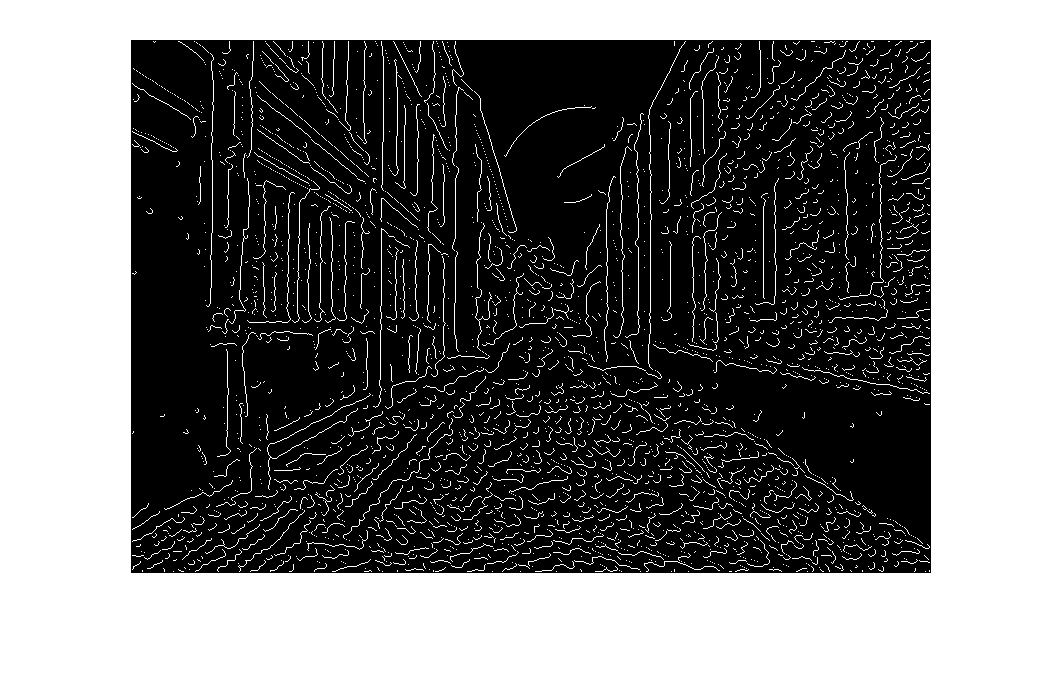

sigma = 3;
width = [20 20];
Iedges = detectZeroCrossings(im, sigma, width);
figure
imshow(Iedges)
% title("Zero Crossings")
saveas(gcf, "zero_crossings.jpg")

### Find Vanishing Point

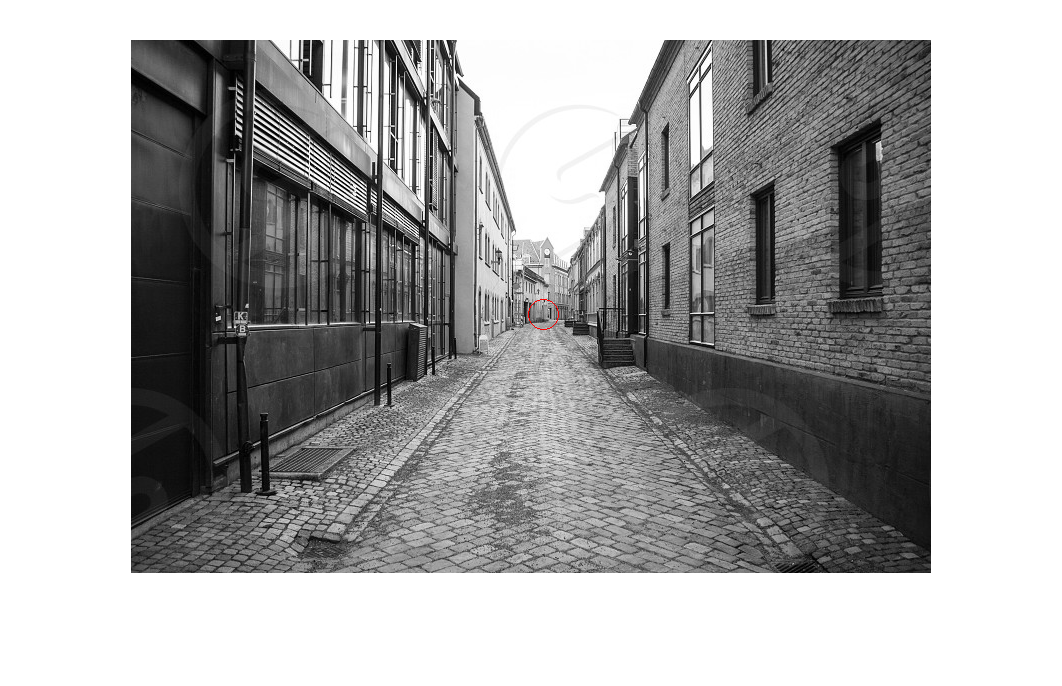

pos = Hough(im, Iedges);
vanishingPoint = insertMarker(im,pos,'o','color','red','size',15);
imshow(vanishingPoint)
% title("Vanishing Point")
saveas(gcf, "vanishing_point.jpg")